%real matlab this time

syms s K
Gs = (s+2/3)/(s^2*(s+6));
Hs = 1;
%open loop Ts
Ts = K * Gs *Hs;

pretty(Ts)

  /     2 \
K | s + - |
  \     3 /
-----------
  2
 s  (s + 6)



[num,den] = numden(Gs);
num = sym2poly(num);
den = sym2poly(den);
sys = tf(num,den)


sys =
 
     3 s + 2
  --------------
  3 s^3 + 18 s^2
 
Continuous-time transfer function.
Model Properties


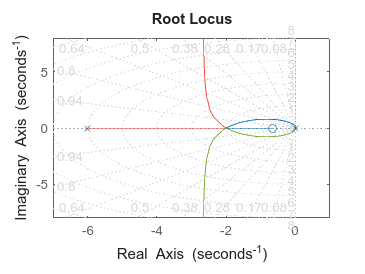


rlocus(sys);
grid on;

Now we're gonna Find the breakaway/breakin oints, the angle between the root locus and the real axis, and the gains at the points.

eqn1 = K == -1*Gs

$$eqn1 = K=-\frac{\left(s-2\right)\,\left(s-3\right)}{s\,\left(s+2\right)\,\left(s+3\right)}$$

eqn2 = simplify(diff(eqn1, s))

$$eqn2 = s\in \mathrm{root}\left(z^{4}-10\,z^{3}-13\,z^{2}+60\,z+36,z\right)$$


breakPoints = subs(eqn2, K, 0)

$$breakPoints = s\in \mathrm{root}\left(z^{4}-10\,z^{3}-13\,z^{2}+60\,z+36,z\right)$$

brekaPoints = solve(breakPoints, s)

$$brekaPoints = \begin{array}{l} \left(\begin{array}{c} \mathrm{root}\left(\sigma_{1},z,1\right)\\ \mathrm{root}\left(\sigma_{1},z,2\right)\\ \mathrm{root}\left(\sigma_{1},z,3\right)\\ \mathrm{root}\left(\sigma_{1},z,4\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=z^{4}-10\,z^{3}-13\,z^{2}+60\,z+36 \end{array}$$

Question 2:

Gs = ((s-2)*(s-3))/ (s*(s+2)*(s+3))

$$Gs = \frac{\left(s-2\right)\,\left(s-3\right)}{s\,\left(s+2\right)\,\left(s+3\right)}$$

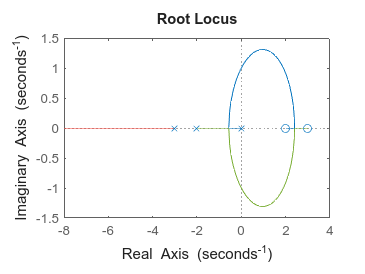

[GsNum,GsDen] = numden(Gs);
GsNum= sym2poly(GsNum);
GsDen= sym2poly(GsDen);
sys = tf(GsNum,GsDen);

rlocus(sys)

Question 3:

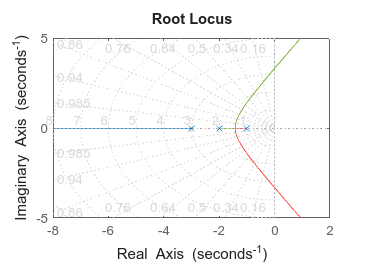

GsDen = ((s+1)*(s+2)*(s+3));
GsNum = 1;
GsDen = sym2poly(GsDen);

sys = tf(GsNum, GsDen);
rlocus(sys);
sgrid(0.5,0);

snake_wn = -0.873
tpThing= 1.68
